## Test prediction with unseen inputs

Given past history of inputs x1 and targets t1 predict given new unseen inputs x2

raw_data = readmatrix('data\biogas_data_clean.xlsx','Sheet','test');
raw_data(:,end) = raw_data(:,end) / 1000;

X = raw_data(:,1:3);
T = raw_data(:,4:5);
x = tonndata(X, false, false);
t = tonndata(T, false, false);
x1 = x(1:10);
t1 = t(1:10);
x2 = x(11:20);
t2 = t(11:20);

load('trained_net.mat', 'net');

y2 = predict(net, x1,t1,x2)

y2 = 1×10 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


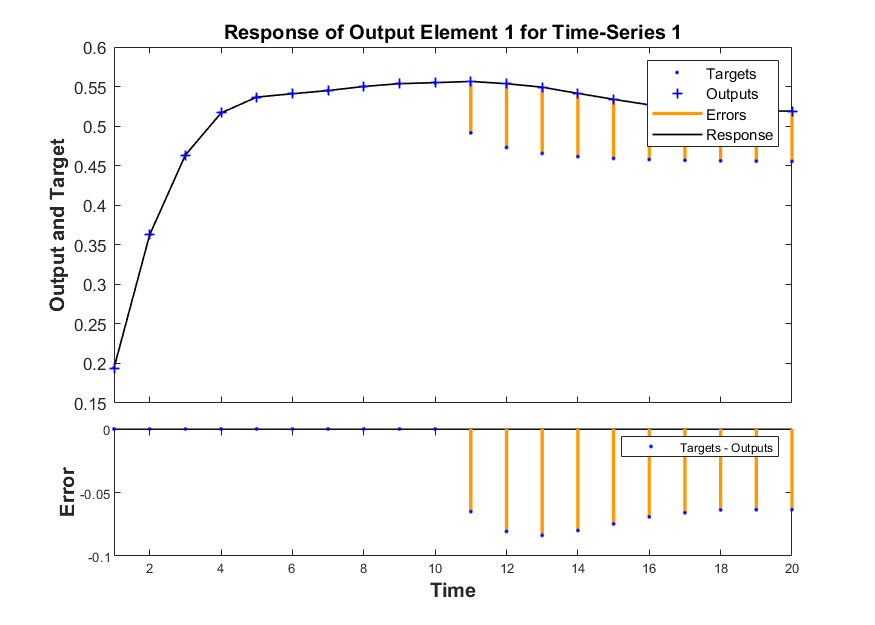

figure
plotresponse(t,[t1 y2], 'outputIndex', 1)

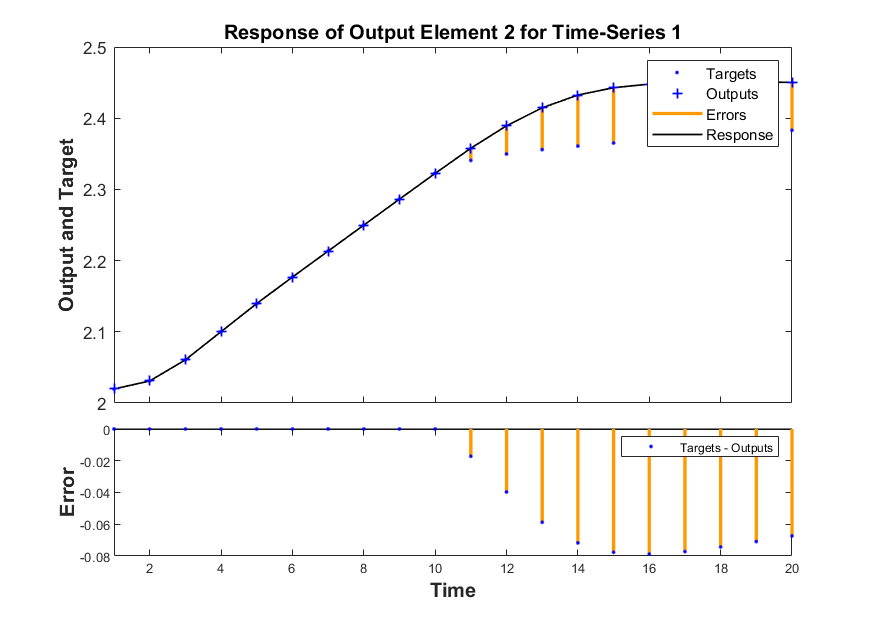

figure
plotresponse(t,[t1 y2], 'outputIndex', 2)